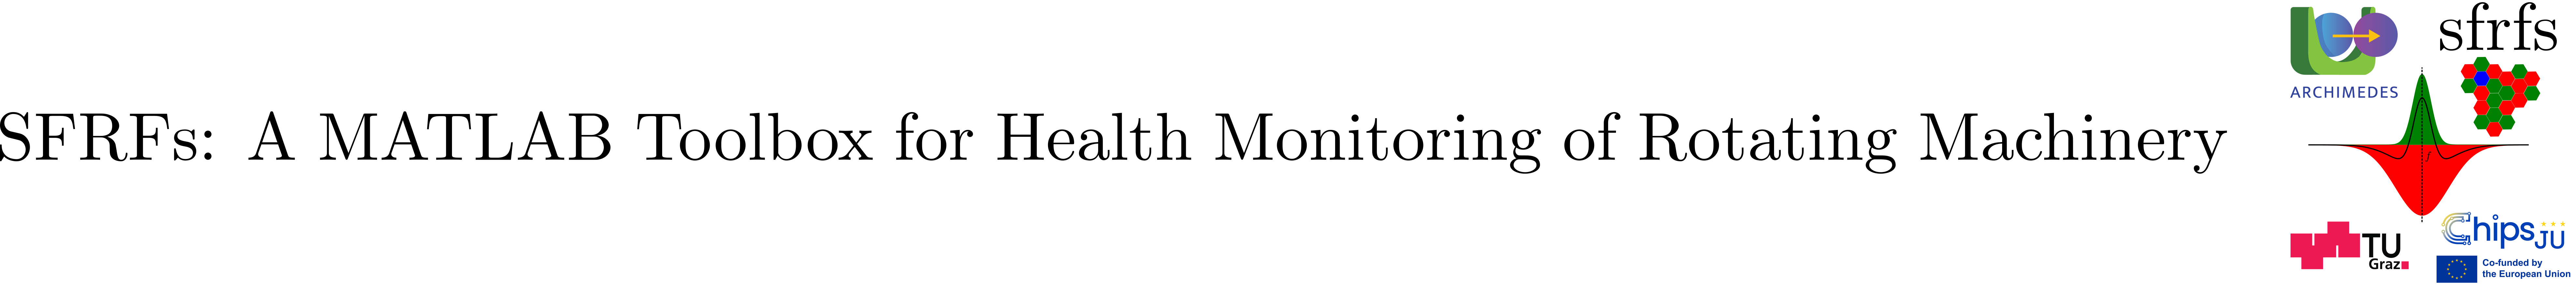

# RunToFailureSpectraViewer

## Summary

Embeddable viewer for run-to-failure spectra over snapshots.

## Description

`RunToFailureSpectraViewer` is a lightweight visualization component for rendering spectra across snapshots of a run-to-failure member table. It plots a spectral matrix (frequency × snapshot index) as an image, enabling direct inspection of spectral evolution over time.

Design:

- No diagnostic masking or receptive-field filtering is applied.

- The viewer renders spectra exactly as provided in the selected spectral column.

- All preprocessing (FFT, normalization, scaling) is assumed to be performed upstream.

### Properties

### Constructor

#### Syntax

- v = viz.RunToFailureSpectraViewer(Name=Value, ...)

#### Parameters (Name=Value)

### Methods

#### renderSpectra selection rules

- Row resolution is not fault-semantic in this viewer. 

- No faultType or selection object is required. 

- The viewer operates directly on the provided member table.

#### renderSpectra parameters (Name=Value)

### See also

[RunToFailureRFGFsFilteredSpectraViewer](matlab:open('./RunToFailureRFGFsFilteredSpectraViewer.mlx')), [RunToFailureSFRFsViewer](matlab:open('./RunToFailureSFRFsViewer.mlx')), [FFTEnsembleProcessor](matlab:open('./FFTEnsembleProcessor.mlx')), [ParametersSnapshot](matlab:open('./ParametersSnapshot.mlx'))

## Example

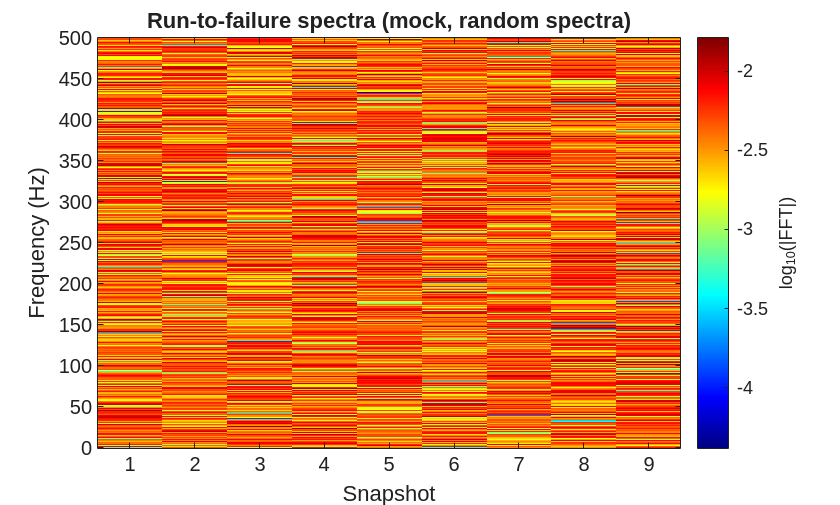

% Example overview
% 1. Define snapshot metadata
% 2. Create mock run-to-failure ensemble
% 3. Create EnsembleBroker
% 4. Execute FFTEnsembleProcessor
% 5. Reconfigure datastore to expose FFT columns
% 6. Read processed member table
% 7. Render run-to-failure spectra

rng(0);

% 1) Snapshot metadata
sp = ParametersSnapshot( ...
    samplingFrequency = 25600, ...
    duration = 1.28, ...
    stride = 60);

speeds = [35; 37.5; 40];
loads  = [12; 11; 10];

% 2) Mock ensemble
temporalCols = {"HorizontalAcceleration"};

mock = EnsembleMock( ...
    numMembers = 1, ...
    nSamples = sp.getTotalSamples(), ...
    speeds = speeds, ...
    loads = loads);

mock.prepare();
clean = onCleanup(@() mock.cleanup());

% 3) Broker
broker = EnsembleBroker( ...
    ensembleObject = mock.fileEnsembleDS, ...
    getFilesFunction = @(o) o.Files, ...
    temporalSnapshotColumns = temporalCols);

% 4) FFT processor
p = FFTEnsembleProcessor(numWorkers = 2, ensemble = broker);
p.process();

% 5) Reconfigure datastore to expose FFT columns
fftCols = string(cellfun( ...
    @(c) broker.mapToSpectralColumn(c), ...
    temporalCols, ...
    UniformOutput = false)).';

ensName = "mock-ensemble";
EnsembleDatastoreRegistry.addEnsemble( ...
    name = ensName, ...
    datastore = broker.ensemble);

ens = EnsembleDatastoreRegistry.reconfigureEnsemble( ...
    name = ensName, ...
    DataVariables = unique([ ...
        broker.ensemble.DataVariables(:); fftCols(:)], "stable"), ...
    SelectedVariables = unique([ ...
        broker.ensemble.SelectedVariables(:); fftCols(:)], "stable"));

% 6) Read member table
reset(ens);
member = read(ens);

% 7) Viewer + render
v = viz.RunToFailureSpectraViewer( ...
    memberTable = member, ...
    snapshotParameters = sp);

specCol = broker.mapToSpectralColumn("HorizontalAcceleration");

ax = v.renderRunToFailure( ...
    spectralColumn = specCol, ...
    freqRange = [0 500], ...
    titleText = "Run-to-failure spectra (mock, random spectra)");

xlabel(ax, "Snapshot");
ylabel(ax, "Frequency (Hz)");

## API documentation

### MATLAB help

help viz.RunToFailureSpectraViewer

 RunToFailureSpectraViewer  Plot run-to-failure FFT snapshots as an image.
 
  Renders a member table (one run-to-failure sequence) as an image:
    y-axis: frequency (Hz), first half only (one-sided)
    x-axis: snapshot index (table row order)
 
  Color encodes log10(|FFT|), normalized by FFT length.
 
  Preconditions:
    memberTable contains a spectral column with one FFT vector per snapshot
    stored as a cell array, consistent size across snapshots.

    Documentation for viz.RunToFailureSpectraViewer



## Source code

The source of the class can be found in [RunToFailureSpectraViewer](matlab:open('../../+viz/RunToFailureSpectraViewer.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).